clear; clc; close all;

%% Experiment 3: PID Compensation for DC Motor - Prelab

s = tf('s');

%% 1. Plant Definition
Gp = 302.5 / (s*(s+35.09)*(1+s/40));

disp('Plant Gp(s) = ');

Plant Gp(s) = 


Gp


Gp =
 
           12100
  ------------------------
  s^3 + 75.09 s^2 + 1404 s
 
Continuous-time transfer function.


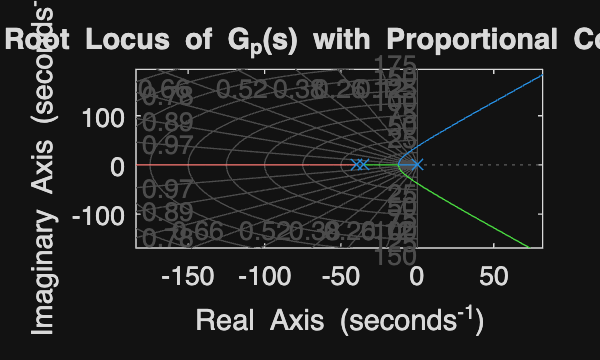


%% 2. Find Critical Gain (Kc) and Critical Period (Tc)
figure;
rlocus(Gp);
grid on;
title('Root Locus of G_p(s) with Proportional Control');


[GM, PM, Wcg, Wcp] = margin(Gp);

% For Z-N ultimate gain method:
% GM = gain margin = Kc
% margin returns [Gm,Pm,Wcg,Wcp]
% Wcg = gain crossover frequency (phase margin freq)
% Wcp = phase crossover frequency (gain margin freq)

Kc = GM;
Tc = 2*pi / Wcp;

fprintf('--- Ziegler-Nichols Ultimate Gain Method ---\n');

--- Ziegler-Nichols Ultimate Gain Method ---


fprintf('Critical Gain Kc = %.4f\n', Kc);

Critical Gain Kc = 8.7104


fprintf('Critical Period Tc = %.4f s\n\n', Tc);

Critical Period Tc = 0.7642 s




%% 3. Ziegler-Nichols PID Parameters
Kp = 0.6*Kc;
Ti = Tc/2;
Td = Tc/8;

Ki = Kp/Ti;
Kd = Kp*Td;

fprintf('--- PID Parameters ---\n');

--- PID Parameters ---


fprintf('Kp = %.4f\n', Kp);

Kp = 5.2263


fprintf('Ti = %.4f s\n', Ti);

Ti = 0.3821 s


fprintf('Td = %.4f s\n', Td);

Td = 0.0955 s


fprintf('Ki = %.4f\n', Ki);

Ki = 13.6771


fprintf('Kd = %.4f\n\n', Kd);

Kd = 0.4993



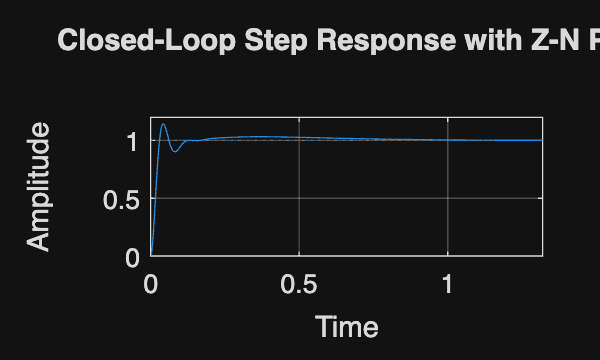


%% 4. Closed-Loop System with PID
C_pid = Kp + Ki/s + Kd*s;
T_sys = feedback(C_pid*Gp, 1);

figure;
step(T_sys);
grid on;
title('Closed-Loop Step Response with Z-N PID');


%% 5. Closed-Loop Poles and Zeros
p = pole(T_sys);
z = zero(T_sys);

disp('Closed-loop poles:');

Closed-loop poles:


disp(p);

 -33.0287 +75.7157i
 -33.0287 -75.7157i
  -4.5163 + 1.9636i
  -4.5163 - 1.9636i




disp('Closed-loop zeros:');

Closed-loop zeros:


disp(z);

  -5.2340 + 0.0000i
  -5.2340 - 0.0000i



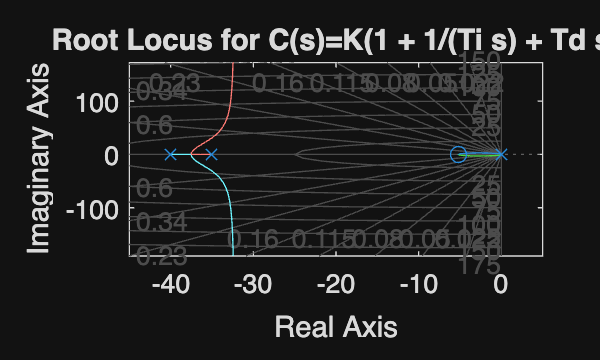


%% 6. Root Locus with fixed Ti and Td, varying overall gain K
Cshape = 1 + 1/(Ti*s) + Td*s;

figure;
rlocus(Cshape*Gp);
grid on;
title('Root Locus for C(s)=K(1 + 1/(Ti s) + Td s)');


%% 7. Derivative Filter Design
fc = 200;             % Hz
wc = 2*pi*fc;         % rad/s
T = 0.001;            % sampling period (1 ms)

Hc = wc/(s + wc);

disp('Continuous-time low-pass filter H(s) = ');

Continuous-time low-pass filter H(s) = 


Hc


Hc =
 
    1257
  --------
  s + 1257
 
Continuous-time transfer function.



%% 8. Discretize filter
H_tustin   = c2d(Hc, T, 'tustin');
H_forward  = c2d(Hc, T, 'foh'); % not Euler; use manual formulas below instead
H_backward = c2d(Hc, T, 'zoh'); % not Euler; use manual formulas below instead

% Manual coefficients for actual Euler approximations:

% Forward Euler:
a1_f = 1 - wc*T;
b0_f = wc*T;
% y(k) = a1_f*y(k-1) + b0_f*x(k-1)

% Backward Euler:
a1_b = 1/(1 + wc*T);
b0_b = (wc*T)/(1 + wc*T);
% y(k) = a1_b*y(k-1) + b0_b*x(k)

% Tustin:
a1_t = (2 - wc*T)/(2 + wc*T);
b0_t = (wc*T)/(2 + wc*T);
b1_t = b0_t;
% y(k) = a1_t*y(k-1) + b0_t*x(k) + b1_t*x(k-1)

fprintf('\n--- Low-pass Filter Recursive Coefficients ---\n');


--- Low-pass Filter Recursive Coefficients ---


fprintf('Forward Euler:\n');

Forward Euler:


fprintf('y(k) = %.6f y(k-1) + %.6f x(k-1)\n', a1_f, b0_f);

y(k) = -0.256637 y(k-1) + 1.256637 x(k-1)



fprintf('\nBackward Euler:\n');


Backward Euler:


fprintf('y(k) = %.6f y(k-1) + %.6f x(k)\n', a1_b, b0_b);

y(k) = 0.443137 y(k-1) + 0.556863 x(k)



fprintf('\nTustin:\n');


Tustin:


fprintf('y(k) = %.6f y(k-1) + %.6f x(k) + %.6f x(k-1)\n', a1_t, b0_t, b1_t);

y(k) = 0.228261 y(k-1) + 0.385870 x(k) + 0.385870 x(k-1)
